## Problem 7.2

Part 1:

Compute $h_L \left\lbrack n\right\rbrack$ for $-20\le n\le 20$ for $L=1,2,3,4$

We know that $h_L \left\lbrack n\right\rbrack =\frac{1}{2\pi }\int_{-\infty }^{\infty } H_L \left(e^{j\omega } \right)e^{j\omega } d\omega$ , $H_L \left(e^{j\omega } \right)=\frac{1}{G_L \left(e^{j\omega } \right)}$, and $G_L \left(e^{j\omega } \right)=\sum_{l=-\infty }^{\infty } |B_L \left(j\left(\omega +2\pi k\right)\right)|^2$

First, we write $G_L \left(e^{j\omega } \right)$ as a function.

% Function of GL used ot calculate value of HL
function y = GL(w, L)
    y = 0;
    % Eval from -100 to 100 to keep bounds reasonable
    for k = -100:100
        y = y + (sin(w./2+pi*k)./(w./2+pi*k)).^(2*L+2);
    end
end

Next, we write a function that evaluates  $h_L \left\lbrack n\right\rbrack =\frac{1}{2\pi }\int_{-\infty }^{\infty } H_L \left(e^{j\omega } \right)e^{j\omega } d\omega$ numerically.

% hl Function
function y = hl(n, L)
    n = n(:).'; 
   
    % Preallocate the output array
    y = zeros(size(n));
    
    for k = 1:length(n)
        y(k) = integral(@(w) cos(w .* n(k)) ./ GL(w, L), -pi, pi) / (2 * pi);
    end
end

Last, plot for all $L=1,2,3,4$

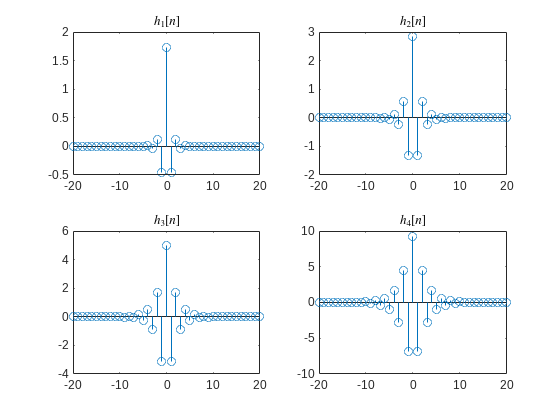

% Eval hl over -20 <= n <= 20
n = -20:20;

figure(1);
subplot(2,2,1)
stem(n, hl(n, 1));
title("$h_1[n]$", 'Interpreter','latex');

subplot(2,2,2)
stem(n, hl(n, 2));
title("$h_2[n]$", 'Interpreter','latex');

subplot(2,2,3)
stem(n, hl(n, 3));
title("$h_3[n]$", 'Interpreter','latex');

subplot(2,2,4)
stem(n, hl(n, 4));
title("$h_4[n]$", 'Interpreter','latex');

Part 2:

We know that $\tilde{b_L } \left(t\right)=\sum_{l=-\infty }^{\infty } h_L \left\lbrack l\right\rbrack b_L \left(t-l\right)$, so we write a function that calculates this numerically.

function y = dual_bsplineN(t, h, L)
    y = 0;
    % We can shrink our bounds to [-20:20] since the splines are very near
    % 0 at 20 and -20.
    for l = -20:20
        y = y + h(l+21).*bsplineN(t-l,L);
    end
end

Lastly, we plot each dual spline function for $L=1,2,3,4$

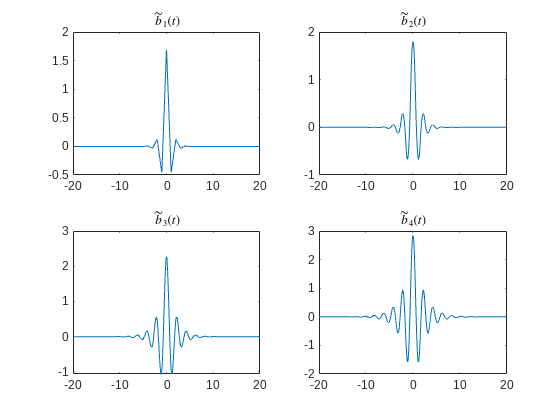

% Eval bspline function over -20 <= t <= 20
t = linspace(-20,20, 1000);
% Eval hl over -20 <= n <= 20
n = -20:20;

figure(2);
subplot(2,2,1);
h1 = hl(n, 1);
plot(t, dual_bsplineN(t, h1, 1));
title("$\tilde{b}_1(t)$", 'Interpreter','latex');

subplot(2,2,2);
h2 = hl(n, 2);
plot(t, dual_bsplineN(t, h2, 2));
title("$\tilde{b}_2(t)$", 'Interpreter','latex');

subplot(2,2,3);
h3 = hl(n, 3);
plot(t, dual_bsplineN(t, h3, 3));
title("$\tilde{b}_3(t)$", 'Interpreter','latex');

subplot(2,2,4);
h4 = hl(n, 4);
plot(t, dual_bsplineN(t, h4, 4));
title("$\tilde{b}_4(t)$", 'Interpreter','latex');

## Problem 7.3

Since $b_L \left(t\right)$ and $\tilde{b_L } \left(t\right)$ are dual bases, $a_n =\int_{-\infty }^{\infty } x\left(t\right)\hat{{\;b}_L } \left(t-n\right)$ and $y\left(t\right)=\sum_{n=-\infty }^{\infty } a_n {\;b}_L \left(t-n\right)$, we can use the previous code to write a function to directly compute y(t).

function y = x_hat(t, x, L)
    y = 0;   
    h = hl(-20:20, L);
    % Evaluate n on both sides of [0,20] bounds of x(t)
    for n = -10:30
        y = y + integral(@(tau) x(tau).*dual_bsplineN(tau-n, h, L), 0, 20).*bsplineN(t-n,L) ;
    end
end

Now, we plot our b-splines approx with the function $x\left(t\right)$ for $L=1,2,3,4$

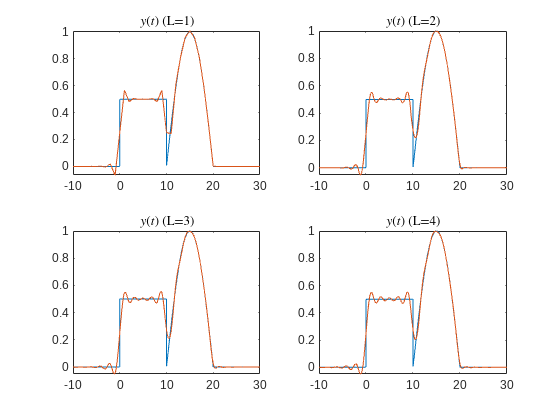

t = linspace(-10, 30, 1000);
x = @(t) (t>=0).*(t<=10).*(0.5) + (t>10).*(t<=20).*(-1.*sin(pi.*t./10));

figure(3);
subplot(2,2,1);
plot(t,x(t)); hold on;
plot(t, x_hat(t, x, 1)); hold off;
title("$y(t)$ (L=1)", 'Interpreter','latex');

subplot(2,2,2);
plot(t,x(t)); hold on;
plot(t, x_hat(t, x, 2)); hold off;
title("$y(t)$ (L=2)", 'Interpreter','latex');

subplot(2,2,3);
plot(t,x(t)); hold on;
plot(t, x_hat(t, x, 3)); hold off;
title("$y(t)$ (L=3)", 'Interpreter','latex');

subplot(2,2,4);
plot(t,x(t)); hold on;
plot(t, x_hat(t, x, 4)); hold off;
title("$y(t)$ (L=4)", 'Interpreter','latex');